Below is a sample code to test out the get_QP function which forms the QP matrices and do_MPC function which calculates the receeding horizon controller for the given system.

clc;
clear;

### Setup up system dynamics and cost function

dT = 0.1; % discretization timestep
A = [1 0 0;1 2 0;1 2 3];
A_d = A.*dT + eye(3);
B = [1 2;2 1;1 3];
B_d = B.*dT;
C = eye(3,3);

Q_i = 1e5*eye(3,3);
R_i = 0.1*eye(2,2);
P = 1e6*eye(3,3);

p = size(B,2);
m = size(C,2);

x0 = [1;1;1];

### Simulate MPC using analytic gain and no constraints

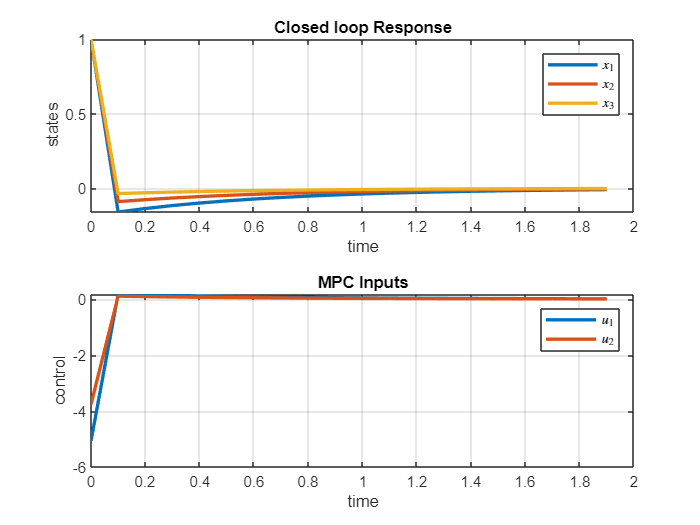

% no constraints
u_min = []; u_max = [];
y_min = []; y_max = [];

% initialize
X = []; U = []; T = [];
x = x0; t = 0;
N = 3; max_iter = 20;

% get QP matrices
[F, G, A_ineq, b_ineq, b_ineq_x0] = get_QP_HW3(A_d,B_d,C,P,Q_i,R_i,N,u_min,u_max,y_min,y_max);
K = -G\F;

% simulate dynamics
for i = 1:max_iter   
    T = [T, t];
    % get RHC control
    u = K*x; u_rhc = u(1:p);
    X = [X, x];
    x = A_d*x + B_d*u_rhc;
    U = [U, u_rhc];
    t = i*dT;
end

% plot
figure()
tiledlayout('flow')
nexttile
plot(T,X, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))
ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');
set(LEG,'interpreter','latex')
nexttile
plot(T,U,'LineWidth',2); grid on;
title(sprintf('MPC Inputs'))
ylabel('control')
xlabel ('time');
LEG = legend('$u_1$', '$u_2$');
set(LEG,'interpreter','latex')

### Simulate MPC using quadprog and no constraints

% using quadprog for no constraints
options = optimoptions('quadprog','Display','off','MaxIterations',1000);

% no constraints
u_min = []; u_max = [];
y_min = []; y_max = [];

%initializze
X = []; U = []; T = [];
x = x0; t = 0;
N = 10; max_iter = 10;

% get QP matrices
[F, G, A_ineq, b_ineq, b_ineq_x0] = get_QP_HW3(A_d,B_d,C,P,Q_i,R_i,N,u_min,u_max,y_min,y_max);

% simulate
for i = 1:max_iter
    T = [T, t];
    f = x'*F';
    u = quadprog(G,f,[],[],[],[],[],[],[],options);
    u = u(1:p);
    X = [X, x];
    x = A_d*x + B_d*u;
    U = [U, u]; t = i*dT;
end 

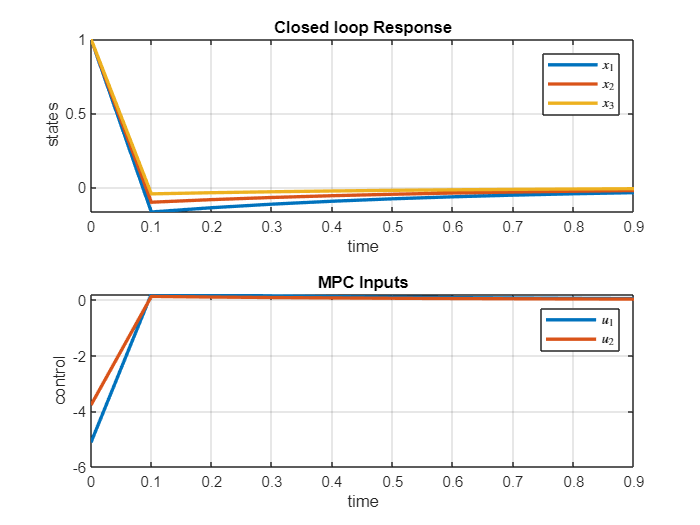


% plot
figure()
tiledlayout('flow')
nexttile
plot(T,X, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))
ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');
set(LEG,'interpreter','latex')
nexttile
plot(T,U,'LineWidth',2); grid on;
title(sprintf('MPC Inputs'))
ylabel('control')
xlabel ('time');
LEG = legend('$u_1$', '$u_2$');
set(LEG,'interpreter','latex')

### Simulate MPC using quadprog with constraints

% using quadprog with constraints
options = optimoptions('quadprog','Display','off');

% constraints
u_min = [-10; -10]; u_max = [10; 10];
y_min = -10*ones(m,1); y_max = 10*ones(m,1);

% initialize
X = []; U = []; T = [];
x = x0; t = 0;
N = 10; max_iter = 10;

% get QP matrices
[F, G, A_ineq, b_ineq, b_ineq_x0] = get_QP_HW3(A_d,B_d,C,P,Q_i,R_i,N,u_min,u_max,y_min,y_max);

%simulate
for i = 1:max_iter
    T = [T, t];
    f = x'*F';
    B_ineq = b_ineq + b_ineq_x0*x;
    u = quadprog(G,f,A_ineq,B_ineq,[],[],[],[],[],options);
    u = u(1:p);
    X = [X, x];
    x = A_d*x + B_d*u;
    U = [U, u]; t = i*dT;
end 

% plot
figure()
tiledlayout('flow')
nexttile
plot(T,X, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))
ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');
set(LEG,'interpreter','latex')
nexttile
plot(T,U,'LineWidth',2); grid on;
title(sprintf('MPC Inputs'))
ylabel('control')
xlabel ('time');
LEG = legend('$u_1$', '$u_2$');
set(LEG,'interpreter','latex')